## Fault Detection of an Inverted Pendulum on a Cart

### Plant Model

- Control `voltage to a DC motor delivers torque to the cart's drive wheel`

- `Position of the cart is measured using a circular coil potentiometer`

- `Velocity of the cart is measured using a tacho generator mounted on the drive wheel`

- `Angle of pendulum is determined via a potentiometer`

- `Angular velocity is not measured`

`System States: `$x= 
\left[ 
\matrix{cart \ position 
\cr cart \ velocity
\cr pendulum \ angle 
\cr pendulum \ angular \ velocity} 
\right]
= 
\left[ 
\matrix{x_{1} \cr x_{2} \cr x_{3}  \cr x_{4}} 
\right]$

#### Plant Parameters

M0 = 3.2;         % [kg]         Pendulum mass
M = 3.529;        % [kg]         Total mass pendulums and the cart
Theta = 0.072;    % [kg.m^2]     Moment of inertia of the pendulum rod
ls = 0.44;        % [m]          Rod length
C = 0.009;        % [kg.m^2/s]   Friction constant of the pendulum
g = 9.81;         % [m/s^2]      Acceleration of gravity
Fr = 6.2;         % [kg/s]       Static friction constant of the cart

% Kr = 2.6;

N = 0.1446;      % [kg.m]        Damping constant at the joints of the rod
N01_2 = 0.23315; % [kg^2.m^2]    Damping constant at the joints of the cart

### `Fault Model`

`We assume a possible fault in the actuator (DC motor drive) `$f_{A}$`, as well as a possible fault in each of the sensors `$f_{s1}$`, `$f_{s2}$`, and `$f_{s3}$`.`


$$f= \left[ \matrix{f_{A1} \cr f_{s1} \cr f_{s2}  \cr f_{s3}} \right]$$


### Linearized Discrete-Tme Model

The system is linearized with a sampling time of  $0.03s$, at the operating point:


$$x=
\left[
\matrix{
r \cr \dot r \cr \phi \cr \dot \phi
}
\right]
=
\left[
\matrix{
0 \cr 0 \cr 0 \cr 0
}
\right]$$


The linearized model is valid under the following conditions:

- Control signal, $\left| F \right| \leq 20N $

- Cart position, $\left| r \right| \leq 0.5m $

- Cart velocity, $\left| \dot r \right| \leq 1m/s$

- Pendulum angle, $\left| \phi \right| \leq \frac{1}{18}\pi \ rad$

#### System Model


$$\dot x= Ax + Bu + E_dd + E_ff \\
y= Cx  + F_ff$$


with:

- state vector, $x$

- input vector, $u$

- disturbance vector, $d$

- fault vector, $f$

A= [
    1, -0.0569,  0.0010, 0.0000;
    0,  0.9442, -0.0038, 0.0000;
    0,  0.0116,  1.0097, 0.0300;
    0,  0.7688,  0.6442,  1.0056
   ];

B= [ 0.0053; -0.1789; 0.0373; 2.4632];

E_d= B;

E_f= [B, zeros(4,3) ];

C= [diag([1,1,1]), zeros(3,1)];

D= zeros(3,1);

F_d= zeros(3,1);

F_f= [zeros(3,1), diag([1,1,1]) ];

% Sampling time
T_s= 0.03;

## State Feedback Control

Because the system is unstable at the linearizaiton point $\left[

\matrix{
0 \cr 0 \cr 0 \cr 0
}
\right]$, we stabilize using a state feedback controller.

We design the gain matrix $K$by placing the poles of $A + BK$as $(0.21, 0.22, 0.23, 0.24)$.

% State feedback controller
feed_poles= [ 0.21; 0.22; 0.23; 0.24 ];
K= place(A, B, feed_poles);


#### Simulation

% No of states
n= size(A,1);
% No of inputs
m= size(B,2);
% No of disturbance inputs
n_d= size(E_d,2);
% No of fault inputs
n_f= size(E_f,2);
% No of outputs
p= size(C,1);

% Number of simulation steps
sim_steps= 15+1;

% Simulatipn time
sim_t= (0:sim_steps)*T_s;

% Pre-allocate matrices to hold simulation data
% Output matrix
y_k= zeros(p, sim_steps);
% State matrix
x_k= zeros(n, sim_steps+1);
% Input matrix
u_k= zeros(m, sim_steps);

% Set initial state into state matrix
x_k(:, 1)= [0; 0; 0.02; 0];


for idx= 1:sim_steps
    % Input
    u_k(:, idx)= -K*x_k(:,idx); 
    % Next state
    x_k(:, (idx+1))= A*x_k(:,idx) + B*u_k(:,idx);
    % Output
    y_k(:, idx)= C*x_k(:,idx);    
end

### Plotting

We plot the state estimation error to visualize the accuracy of the observed states

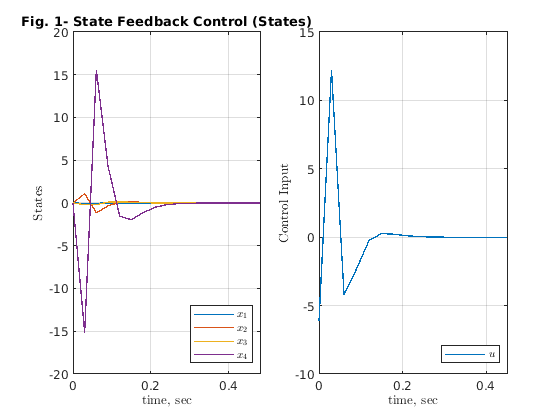

Fig_sfc= figure;

subplot(1,2,1);
plot(sim_t, x_k, 'LineWidth', 1);
grid on;
title('Fig. 1- State Feedback Control (States)');
ylabel('States', 'Interpreter', 'latex'); 
xlabel('time, sec', 'Interpreter', 'latex');
leg= legend(['$x_1$', "$x_2$", '$x_3$', '$x_4$']); 
leg.Interpreter='latex';
leg.Location= 'southeast';

subplot(1,2,2);
plot(sim_t(1:end-1), u_k, 'LineWidth', 1);
grid on;
ylabel('Control Input', 'Interpreter', 'latex'); 
xlabel('time, sec', 'Interpreter', 'latex');
leg= legend(['$u$']); leg.Interpreter='latex';
leg.Location= 'southeast';

## Full Order Observer Design

We want to design a full-order obeserver such that:


$$\dot \hat x= A \hat x + Bu + L(y - \hat y)$$



$$\hat y= C \hat x$$


The observer error dynamics is then governed by:


$$\dot e= (A - LC)e + E_dd + (E_f +LF_f) f$$


with:

- 
$$e= x- \hat x$$


#### Pole Placement

If we select our desired ole positions to be: $(0.011, 0.012, 0.013, 0.014)$, we can examine the possible system response as:

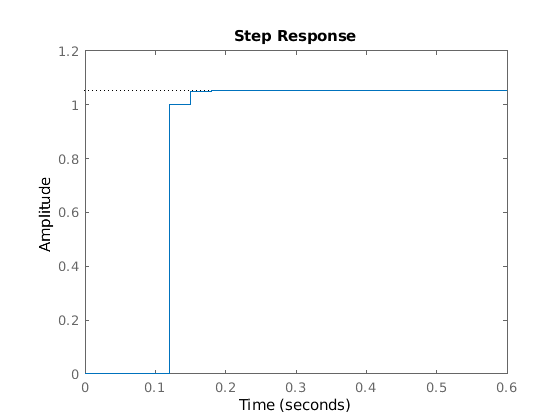

obs_poles= [0.011, 0.012, 0.013, 0.014];
sys_temp= zpk([],obs_poles,1, T_s);
figure
step(sys_temp)

As can be seen, the response is quite satisfactory, with a response time of about $2\times 10^{-3}$.

Now we compute the gain matrix $L$ for our full order observer as:

L= place(A', C', obs_poles)'

L =     0.9870   -0.0569    0.0010
         0    0.9302   -0.0038
    0.0000    0.0116    1.9923
    0.0000    0.7688   33.5854


### Full Order Observer Simulation

Here, we compare system states and output with the full order observer under zero disturbance and an initial state of  $x= 
\left [
\matrix{
0 \cr 0 \cr 0.02 \cr 0
}
\right ]$.

Because the system is unstable at the linearizaiton point $\left[

\matrix{
0 \cr 0 \cr 0 \cr 0
}
\right]$, we stabilize using a state feedback controller.

We design the gain matrix $K$by placing the poles of $A + BK$as $(0.21, 0.22, 0.23, 0.24)$.

% State feedback controller
feed_poles= [ 0.21; 0.22; 0.23; 0.24 ];
K= place(A, B, feed_poles);


#### Simulation

% Number of simulation steps
sim_steps= 15+1;

% Simulatipn time
sim_t= (0:sim_steps)*T_s;

% Pre-allocate matrices to hold simulation data
% Output matrix
y_k= zeros(p, sim_steps);
% State matrix
x_k= zeros(n, sim_steps+1);
% Input matrix
u_k= zeros(m, sim_steps);

% Observed state matrix
x_k_hat= zeros(n, sim_steps+1);
% Observed output matrix
y_k_hat= zeros(p, sim_steps);

% State estimation error
e_k= zeros(n, sim_steps+1);

% Set initial state into state matrix
x_k(:, 1)= [0; 0; 0.02; 0];

% Initial  state estimation error
e_k(:, 1)= x_k(:, 1) - x_k_hat(:, 1);

for idx= 1:sim_steps
    % Input
    u_k(:, idx)= -K*x_k(:,idx); 
    % Next state
    x_k(:, (idx+1))= A*x_k(:,idx) + B*u_k(:,idx);
    % Output
    y_k(:, idx)= C*x_k(:,idx);
    
    % Observed output
    y_k_hat(:, idx)= C*x_k_hat(:,idx);    
    % Observed state
    x_k_hat(:, (idx+1))= A*x_k_hat(:,idx) + B*u_k(:,idx) + ...
        L*( y_k(:, idx) - y_k_hat(:, idx) );
    
    % State estimation error
    e_k(:, idx+1)= x_k(:, idx+1) - x_k_hat(:, idx+1);
    
end

### Plotting

We plot the state estimation error to visualize the accuracy of the observed states

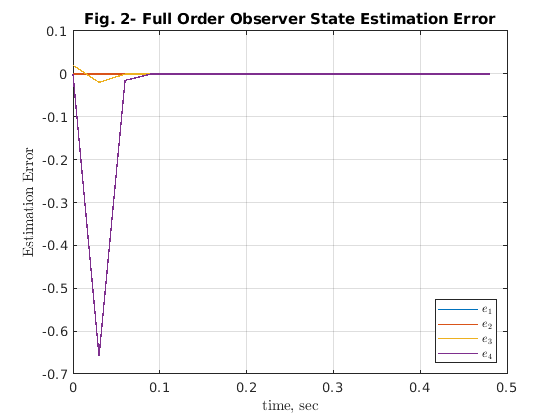

Fig_obs= figure;

plot(sim_t, e_k, 'LineWidth', 1);
grid on;
title('Fig. 2- Full Order Observer State Estimation Error');
ylabel('Estimation Error', 'Interpreter', 'latex'); 
xlabel('time, sec', 'Interpreter', 'latex');
leg= legend(['$e_1$', "$e_2$", '$e_3$', '$e_4$']); leg.Interpreter='latex';
leg.Location= 'southeast';

### Fault Injection and Residual Generation

Now we inject faults into the system. We simulate the faults to happen at $(3.5s, \ 5s, \ 7.5s, \ 12s)$ respectively.

fault_times= [3.5; 5; 7.5; 12];
fault_points= round(fault_times./T_s);

#### Simulation

% Number of simulation steps
sim_steps= fault_points(end)+100;

% Simulatipn time
sim_t= (0:sim_steps)*T_s;

% Pre-allocate matrices to hold simulation data
% Output matrix
y_k= zeros(p, sim_steps);
% State matrix
x_k= zeros(n, sim_steps+1);
% Input matrix
u_k= zeros(m, sim_steps);
% Disturbance Matrix
d_k= 0.5*rand(n_d, sim_steps);
% Fault Matrix
f_k= zeros(n_f, sim_steps);
% Residual Matrix
r_k= zeros(p, sim_steps);
% Reisudual Filter to improve residual dynamics
W= diag([3,2,1]);

% Fault injection
for idx=1:n_f
    f_k(idx, fault_points(idx):end)= ones(1,sim_steps-fault_points(idx)+1);
end


% Observed state matrix
x_k_hat= zeros(n, sim_steps+1);
% Observed output matrix
y_k_hat= zeros(p, sim_steps);

% Set initial state into state matrix
x_k(:, 1)= [0; 0; 0.02; 0];

% Initial  state estimation error
e_k(:, 1)= x_k(:, 1) - x_k_hat(:, 1);

for idx= 1:sim_steps
    % Input
    u_k(:, idx)= -K*x_k(:,idx); 
    % Next state
    x_k(:, (idx+1))= A*x_k(:,idx) + B*u_k(:,idx) + E_d*d_k(:,idx) + E_f*f_k(:,idx);
    % Output
    y_k(:, idx)= C*x_k(:,idx) + F_f*f_k(:,idx);
    
    % Observed output
    y_k_hat(:, idx)= C*x_k_hat(:,idx);    
    % Observed state
    x_k_hat(:, (idx+1))= A*x_k_hat(:,idx) + B*u_k(:,idx) + ...
        L*( y_k(:, idx) - y_k_hat(:, idx) );
    
    % Residual Generation
    r_k(:, idx)= W*( y_k(:,idx) - y_k_hat(:,idx) );
    
end

### Plotting

We plot the state estimation error to visualize the accuracy of the observed states

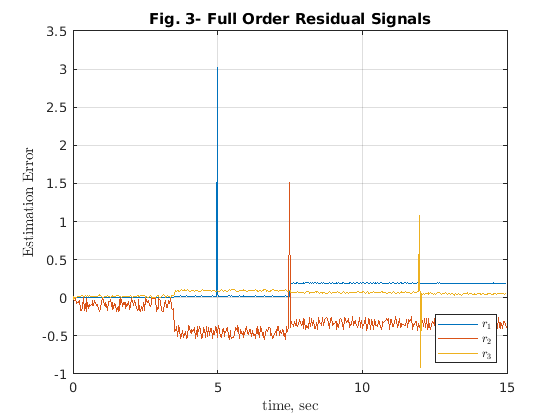

Fig_res= figure;

plot(sim_t(1:end-1), r_k, 'LineWidth', 1);
grid on;
title('Fig. 3- Full Order Residual Signals');
ylabel('Estimation Error', 'Interpreter', 'latex'); 
xlabel('time, sec', 'Interpreter', 'latex');
leg= legend(['$r_1$', "$r_2$", '$r_3$']); leg.Interpreter='latex';
leg.Location= 'southeast';

### Full Decoupling using Unknown Input Observer

We try to eliminate the influence of the disturbance signals on the residual by usung an Unknown Input Observer.

Assuming a fault-free operation, we have:


$$\dot x= Ax + Bu + E_d d \\
y= Cx$$


By taking the derivative of $y$, we have:


$$\dot y= C( Ax + Bu + E_d d )$$


We need $C E_d$ to be left-invertible (of full column rank), such that:


$$d= {C E_d}^{-1}(\dot y - CAx - CBu)$$


With $M = {C E_d}^{-1}$ we have:


$$\dot x= (A - E_{d}MCA)x + (B - E_{d}MCB)u + E_{d}M \dot y$$


To avoid using the derivative of the ooutput signal, we can perform a state transformation:


$$z= x - E_{d}My$$


Such that:


$$\dot z= (A - E_{d}MCA)x + (B - E_{d}MCB)u$$


for which we can then construct an observer.

% Checking if CE_d is left-invertible
C_E_d= C*E_d;
size(C_E_d)

ans =      3     1


% Not square- i.e. not invertible

Hoewever, for this plant, $C E_d$ is not invertible, thus this approach cannot be used.

## Parity Space Approach

With the parity space approach, we explore the inherent characteristics of the system to generate residual signals. 

First, we examine the behaviour of the system over a window of length $s$


$$y(k-s)= Cx(k-s) + Du(k-s) + F_{d}d(k-s) + F_{f}f(k-s)
$$



$$y(k-s+1)= Cx(k-s+1) + Du(k-s+1) + F_{d}d(k-s+1) + F_{f}f(k-s+1) \\
y(k-s+1)= CAx(k-s) + CBu(k-s) + CE_dd+ CE_ff + Du(k-s+1) + F_{d}d(k-s+1) + F_{f}f(k-s+1)$$



$$\cdot  \\  
\cdot  \\  
\cdot$$



$$y(s)= 
CA^{s}x(k-s) + CA^{s-1}Bu(k-s) + \cdot \cdot \cdot + CBu(k-1) + Du(k) + CA^{s-1}E_dd(k-s) + \cdot \cdot \cdot + CE_dd(k-1) +  \\ \ \ \ \ \ 
F_dd(k) + CA^{s-1}E_ff(k-s) + \cdot \cdot \cdot + CE_ff(k-1) + F_ff(k)  $$


If we stack up all the equations into matrix form, we have


$$\left[
\matrix{
y(k-s) \cr
y(k-s+1) \cr
y(k-s+2) \cr
\cdot \cr
\cdot \cr
\cdot \cr
y(k-1) \cr
y(k)

}
\right]
=
\left[
\matrix{
C \cr
CA \cr
CA^2 \cr
\cdot \cr
\cdot \cr
\cdot \cr
CA^{s-1} \cr
CA^s
}
\right]
x(k-s)
+
\left[
\matrix{
D & 0 & 0 & \cdot & \cdot & \cdot & 0 & 0 \cr
CB & D & 0 & \cdot & \cdot & \cdot & 0 & 0 \cr
CAB & CB & D & \cdot & \cdot & \cdot & 0 & 0 \cr
\cdot \cr
\cdot \cr
\cdot \cr
CA^{s-2}B & CA^{s-3}B & CA^{s-4}B & \cdot & \cdot & \cdot & D & 0 \cr
CA^{s-1}B & CA^{s-2}B & CA^{s-3}B & \cdot & \cdot & \cdot & CB & D \cr
}
\right]
\\ \ \ \ \ \ \ \ \ \ \ \ \ \ 
+
\left[
\matrix{
F_d & 0 & 0 & \cdot & \cdot & \cdot & 0 & 0 \cr
CE_d & F_d & 0 & \cdot & \cdot & \cdot & 0 & 0 \cr
CAE_d & CE_d & F_d & \cdot & \cdot & \cdot & 0 & 0 \cr
\cdot \cr
\cdot \cr
\cdot \cr
CA^{s-2}E_d & CA^{s-3}E_d & CA^{s-4}E_d & \cdot & \cdot & \cdot & F_d & 0 \cr
CA^{s-1}E_d & CA^{s-2}E_d & CA^{s-3}E_d & \cdot & \cdot & \cdot & CE_d & F_d \cr
}
\right]
+
\left[
\matrix{
F_f & 0 & 0 & \cdot & \cdot & \cdot & 0 & 0 \cr
CE_f & F_f & 0 & \cdot & \cdot & \cdot & 0 & 0 \cr
CAE_f & CE_f & F_f & \cdot & \cdot & \cdot & 0 & 0 \cr
\cdot \cr
\cdot \cr
\cdot \cr
CA^{s-2}E_f & CA^{s-3}E_f & CA^{s-4}E_f & \cdot & \cdot & \cdot & F_f & 0 \cr
CA^{s-1}E_f & CA^{s-2}E_f & CA^{s-3}E_f & \cdot & \cdot & \cdot & CE_f & F_f \cr
}
\right]$$


We can then compress this into


$$y_{s}(k)= H_{o,s} x(k-s) + H_{u,s} u_{s}(k) + H_{d,s} d_{s}(k) + H_{f,s} f_{s}(k)$$


Rearranging yields


$$y_{s}(k) - H_{u,s} u_{s}(k) = H_{o,s} x(k-s) + H_{d,s} d_{s}(k) + H_{f,s} f_{s}(k)$$


Since $y_s(k)$and $u_s(k)$are available online, we generate the residual signal as


$$r(k)= v_s ( y_s(k) - H_{u,s} u_{s}(k) )$$


The dynamics of the residual are now governed by 


$$r(k) = v_s \left( H_{o,s} x(k-s) + H_{d,s} d_{s}(k) + H_{f,s} f_{s}(k) \right)$$


The vector $v_s$ is called the parity vector and must satisfy:

- 
$$v_s H_{o,s}= 0$$


- 
$$v_s H_{f,s} \ne 0$$


- $v_s H_{d,s}= 0$ (for full decoupling)

For full decoupling to be possible, the following rank condition must be satisfied:


$$rank\left[ H_{o,s} \ H_{d,s} \right] \lt rank\left[ H_{o,s} \ H_{d,s} \ H_{f,s} \right]$$


#### Build up data matrices

% Window size
s= 5;

% H_os, H_us, H_ds, H_fs
H_os = zeros(s*p,n);
H_us= zeros(s*p,s*m);
H_ds= zeros(s*p,s*n_d);
H_fs= zeros(s*p,s*n_f);

for r = 1:s
    H_os((r-1)*p+1:r*p,1:n) = C*(A^(r-1));
    for c = 1:r
        if r == c
            H_us((r-1)*p+1:r*p,(c-1)*m+1:c*m) = D;
            H_ds((r-1)*p+1:r*p,(c-1)*n_d+1:c*n_d) = F_d;
            H_fs((r-1)*p+1:r*p,(c-1)*n_f+1:c*n_f) = F_f;
        else 
            H_us((r-1)*p+1:r*p,(c-1)*m+1:c*m) = C*A^(r-c-1)*B;
            H_ds((r-1)*p+1:r*p,(c-1)*n_d+1:c*n_d) = C*A^(r-c-1)*E_d;
            H_fs((r-1)*p+1:r*p,(c-1)*n_f+1:c*n_f) = C*A^(r-c-1)*E_f;
        end
    end
end


% Check rank condition for full decoupling
rank([H_os H_ds]) < rank([H_os H_ds H_fs])

ans = logical
   1


Since the rank condition is satisfied, full decoupling can be achieved.

#### Parity Vector

% Left null space of H_os H_ds
N_basis= null([H_os H_ds]')';

% Parity vector (can be selected as any of the rows)
v_s= N_basis(1, :)

v_s =    -0.0727    0.0363   -0.1677    0.1874    0.1251   -0.2757   -0.0701    0.0076    0.8571   -0.0248   -0.1293   -0.1783   -0.0198   -0.0459   -0.2175


Pre-computation of $v_s H_{u,s}$ to speed up online computation

rho_s= v_s*H_us

rho_s = 	1.0e+-16 *

    0.1388    0.3469    0.1735    0.0694         0


### Simulation

% Number of simulation steps
sim_steps= fault_points(end)+100;

% Simulatipn time
sim_t= (0:sim_steps)*T_s;

% Pre-allocate matrices to hold simulation data
% Output matrix
y_k= zeros(p, sim_steps);
% State matrix
x_k= zeros(n, sim_steps+1);
% Input matrix
u_k= zeros(m, sim_steps);
% Disturbance Matrix
d_k= 0.5*rand(n_d, sim_steps);
% Fault Matrix
f_k= zeros(n_f, sim_steps);
% Residual Matrix
r_k= zeros(1, (sim_steps-s));

% Fault injection
for idx=1:n_f
    f_k(idx, fault_points(idx):end)= ones(1,sim_steps-fault_points(idx)+1);
end


% Set initial state into state matrix
x_k(:, 1)= [0; 0; 0.02; 0];

% Before time k
% We need prior data for k-s to be valid
for idx= 1:(s+1)
    % Input
    u_k(:, idx)= -K*x_k(:,idx); 
    % Next state
    x_k(:, (idx+1))= A*x_k(:,idx) + B*u_k(:,idx) + E_d*d_k(:,idx);
    % Output
    y_k(:, idx)= C*x_k(:,idx) + D*u_k(:,idx) + F_d*d_k(:,idx);
end

% After Time k
for idx= (s+1):sim_steps
    % Input
    u_k(:, idx)= -K*x_k(:,idx); 
    % Next state
    x_k(:, (idx+1))= A*x_k(:,idx) + B*u_k(:,idx) + E_d*d_k(:,idx) + E_f*f_k(:, idx);
    % Output
    y_k(:, idx)= C*x_k(:,idx) + D*u_k(:,idx) + F_d*d_k(:,idx) + F_f*f_k(:, idx);
    
    % Residual Generation
    % y_s
    y_s_k= y_k(:, (idx-s+1):(idx));
    y_s_k= y_s_k(:);
    % u_s
    u_s_k= u_k(:, (idx-s+1):(idx));
    u_s_k= u_s_k(:);
    % Residual
    r_k(:, (idx-s))= v_s*y_s_k - rho_s*u_s_k;
    
end


### Plotting

We plot the state estimation error to visualize the accuracy of the observed states

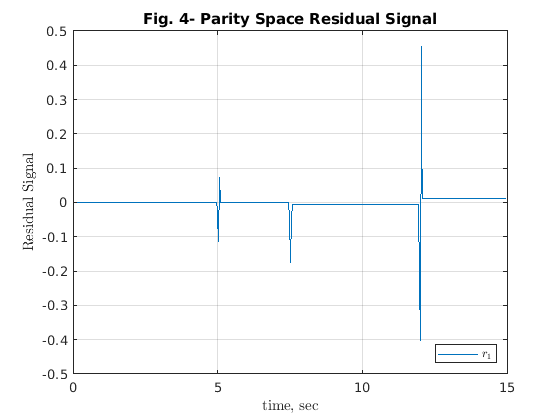

Fig_ps_res= figure;

plot(sim_t(s+1:end-1), r_k, 'LineWidth', 1);
grid on;
title('Fig. 4- Parity Space Residual Signal');
ylabel('Residual Signal', 'Interpreter', 'latex'); 
xlabel('time, sec', 'Interpreter', 'latex');
leg= legend(['$r_1$']); leg.Interpreter='latex';
leg.Location= 'southeast';

As can be seen in the figure above, the generated residual is insensitive to the actuator fault, this is probably because $B= E_d$.

If the residual signal is decoupled from the disturbance (via $E_d$), then it is effectively decoupled from the input (via $B$).

**System States**

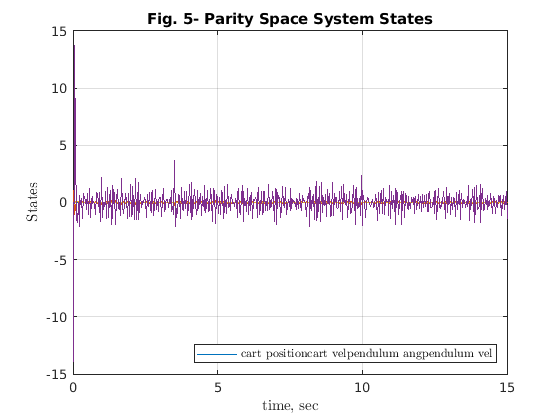

Fig_ps_states= figure;

plot(sim_t, x_k, 'LineWidth', 1);
grid on;
title('Fig. 5- Parity Space System States');
ylabel('States', 'Interpreter', 'latex'); 
xlabel('time, sec', 'Interpreter', 'latex');
leg= legend(['cart position', 'cart vel', 'pendulum ang', 'pendulum vel']); leg.Interpreter='latex';
leg.Location= 'southeast';

### References

[Fault Diagnosis and Fault Tolerant Systems Exercises, TU Kaiserslautern- Dina Martynova](https://www.eit.uni-kl.de/atplus/lehrstuhl/wissenschaftliche-mitarbeiter/m-sc-dina-mikhaylenko/)